% ==========================================================
% main_generator.m - 主数据生成脚本
% ==========================================================
clear; clc; close all;
tic
% --- 1. 公共参数设置 ---
params.fs = 80e6;        % 采样频率 100MHz
params.fc = 40e6;        % 中心频率 40MHz
params.B = 10e6;         % 带宽    10MHz
params.taup = 20e-6;     % LFM脉宽 20us
params.Np = 1;           % 脉冲个数 1  ->只在单个PRI内测试
params.PRI = 100e-6;     % 脉冲重复间隔 us
params.SNR = 15;         % 信噪比
% params.JNR = 15;         % 干噪比 (可以为不同干扰类型单独设置)
% JNR_values = 0:5:40;    %干噪比范围 dB
JNR_values = 15;    % 干噪比范围 dB
params.numClasses = 16;    % 基础九种干扰
SAMPLE_NUM_S = 5;
SAMPLE_NUM_M = 200;
params.pos = 1000+randi([0 6000]);      %在PRI中第5000点处
% --- 2. 生成计划 ---
% 定义要生成的干扰类型和对应的标签
generation_plan = {
    % 欺骗干扰
    'DFTJ' , 1,  SAMPLE_NUM_S;
    % 'ISRJ' , 2,  SAMPLE_NUM_S;
    % 'SMSPJ', 10, SAMPLE_NUM_S;
    % 'C&IJ' , 11, SAMPLE_NUM_S;
    % 'CSJ'  , 15, SAMPLE_NUM_S;
    % 'RGPO' , 3,  SAMPLE_NUM;
    % 'VGPO' , 4,  SAMPLE_NUM;

    % 压制干扰
    % 'AJ'   , 5, SAMPLE_NUM_S;
    % 'BJ'   , 6, SAMPLE_NUM_S;
    % 'SJ'   , 7, SAMPLE_NUM_S;
    % 'NCJ'  , 8, SAMPLE_NUM_S;
    % 'NPJ'  , 9, SAMPLE_NUM_S;
    % 'NFMJ' , 12, SAMPLE_NUM_S;
    % 'NPMJ' , 13, SAMPLE_NUM_S;
    % 'NAMJ' , 14, SAMPLE_NUM_S;
    % 'PJ'   , 16, SAMPLE_NUM_S;

    % 在这里添加更多类型，例如 'sweep', 3, 200

    % 'DFTJ+AJ',  [1,5] , SAMPLE_NUM_M;
    % 'DFTJ+BJ',  [1,6] , SAMPLE_NUM_M;
    % 'DFTJ+SJ',  [1,7] , SAMPLE_NUM_M;
    % 'DFTJ+NCJ', [1,8] , SAMPLE_NUM_M;
    % 'DFTJ+NPJ', [1,9] , SAMPLE_NUM_M;
    % 'DFTJ+NFMJ',[1,12] , SAMPLE_NUM_M;
    % 'DFTJ+NPMJ',[1,13] , SAMPLE_NUM_M;
    % 'DFTJ+NAMJ',[1,14] , SAMPLE_NUM_M;
    % 'DFTJ+PJ',  [1,16] , SAMPLE_NUM_M;
    %
    %
    % 'ISRJ+AJ', [2,5] , SAMPLE_NUM_M;
    % 'ISRJ+BJ', [2,6] , SAMPLE_NUM_M;
    % 'ISRJ+SJ', [2,7] , SAMPLE_NUM_M;
    % 'ISRJ+NCJ', [2,8] , SAMPLE_NUM_M;
    % 'ISRJ+NPJ', [2,9] , SAMPLE_NUM_M;
    % 'ISRJ+NFMJ',[2,12] , SAMPLE_NUM_M;
    % 'ISRJ+NPMJ',[2,13] , SAMPLE_NUM_M;
    % 'ISRJ+NAMJ',[2,14] , SAMPLE_NUM_M;
    % 'ISRJ+PJ',  [2,16] , SAMPLE_NUM_M;
    %
    % 'SMSPJ+AJ', [10,5] , SAMPLE_NUM_M;
    % 'SMSPJ+BJ', [10,6] , SAMPLE_NUM_M;
    % 'SMSPJ+SJ', [10,7] , SAMPLE_NUM_M;
    % 'SMSPJ+NCJ', [10,8] , SAMPLE_NUM_M;
    % 'SMSPJ+NPJ', [10,9] , SAMPLE_NUM_M;
    % 'SMSPJ+NFMJ',[2,12] , SAMPLE_NUM_M;
    % 'SMSPJ+NPMJ',[2,13] , SAMPLE_NUM_M;
    % 'SMSPJ+NAMJ',[2,14] , SAMPLE_NUM_M;
    % 'SMSPJ+PJ',  [2,16] , SAMPLE_NUM_M;
    %
    % 'C&IJ+AJ', [11,5] , SAMPLE_NUM_M;
    % 'C&IJ+BJ', [11,6] , SAMPLE_NUM_M;
    % 'C&IJ+SJ', [11,7] , SAMPLE_NUM_M;
    % 'C&IJ+NCJ', [11,8] , SAMPLE_NUM_M;
    % 'C&IJ+NPJ', [11,9] , SAMPLE_NUM_M;
    % 'C&IJ+NFMJ',[2,12] , SAMPLE_NUM_M;
    % 'C&IJ+NPMJ',[2,13] , SAMPLE_NUM_M;
    % 'C&IJ+NAMJ',[2,14] , SAMPLE_NUM_M;
    % 'C&IJ+PJ',  [2,16] , SAMPLE_NUM_M;
    %
    % 'CSJ+AJ', [15,5] , SAMPLE_NUM_M;
    % 'CSJ+BJ', [15,6] , SAMPLE_NUM_M;
    % 'CSJ+SJ', [15,7] , SAMPLE_NUM_M;
    % 'CSJ+NCJ', [15,8] , SAMPLE_NUM_M;
    % 'CSJ+NPJ', [15,9] , SAMPLE_NUM_M;
    % 'CSJ+NFMJ',[2,12] , SAMPLE_NUM_M;
    % 'CSJ+NPMJ',[2,13] , SAMPLE_NUM_M;
    % 'CSJ+NAMJ',[2,14] , SAMPLE_NUM_M;
    % 'CSJ+PJ',  [2,16] , SAMPLE_NUM_M;

    };

% --- 3. 执行生成 ---
[tx, params] = generate_0base_signal(params);
toc

历时 0.065774 秒。



%% 循环生成每种干扰
len = size(generation_plan, 1);
SAMPLE_NUM = sum( [generation_plan{:, 3}])

SAMPLE_NUM = 5

tic
for current_jnr = JNR_values
    % 初始化数据容器
    current_jnr
    all_times = zeros(SAMPLE_NUM,params.PRI_samp);
    all_label = zeros(SAMPLE_NUM,params.numClasses);
    Nwin = 128; Noverlap = 64;
    Step = Nwin - Noverlap;
    N_cols = floor((params.N_total - Noverlap) / Step);
    Nfft = 64;
    all_stfts = zeros(SAMPLE_NUM,Nfft,N_cols);
    point_l = 1;
    for i = 1:len
        % 生成基础目标信号 (所有干扰类型共用)

        jam_type = generation_plan{i, 1};
        label = generation_plan{i, 2};
        num_to_generate = generation_plan{i, 3};
        % fprintf('正在生成 %d 个 [%s] 类型的样本, 标签为 %s...\n', num_to_generate, jam_type, num2str(label));

        Aj = 10^(current_jnr/20);
        % 创建当前SNR值的子文件夹
        % 获取当前时间
        current_datetime = datetime('now', 'Format', 'yyMMdd');
        % 转换为字符串
        time_str = char(current_datetime);
        % 构建目录路径
        snr_output_dir = fullfile(time_str, sprintf('JNR_%+d', current_jnr));

        if ~exist(snr_output_dir, 'dir')
            mkdir(snr_output_dir);
        end
        % fprintf('Generating data for JNR = %d dB...\n', current_jnr);
        %%% jam_type,params,current_jnr,all_labels

        [new_times, new_label] = multi_generation(label,params,current_jnr,num_to_generate);
        if i ~= 1
            point_l = point_r + 1;
        end
        point_r = point_l + num_to_generate-1;
        all_times(point_l:point_r,:) = new_times;
        all_label(point_l:point_r,:) = new_label;

        % 追加到总数据集中
    end
    for i = 1:SAMPLE_NUM
        [S,F,T] = spectrogram(all_times(i,1:params.PRI_samp),Nwin,Noverlap,Nfft,params.fs, 'centered');
        all_stfts(i,:,:) = S;
    end

    % path_stfts = fullfile(snr_output_dir, 'train_echo_stfts.mat');
    % path_times = fullfile(snr_output_dir, 'train_echo_times.mat');
    % path_label = fullfile(snr_output_dir, 'train_echo_label.mat');

    % path_stfts = fullfile(snr_output_dir, 'test_echo_stfts.mat');
    % path_times = fullfile(snr_output_dir, 'test_echo_times.mat');
    % path_label = fullfile(snr_output_dir, 'test_echo_label.mat');
    %
    path_stfts = fullfile(snr_output_dir, 'val_echo_stfts.mat');
    path_times = fullfile(snr_output_dir, 'val_echo_times.mat');
    path_label = fullfile(snr_output_dir, 'val_echo_label.mat');

    save(path_stfts, 'all_stfts', '-v7.3');
    save(path_times, 'all_times', '-v7.3');
    save(path_label, 'all_label', '-v7.3');
end

current_jnr = 15

toc

历时 0.189953 秒。


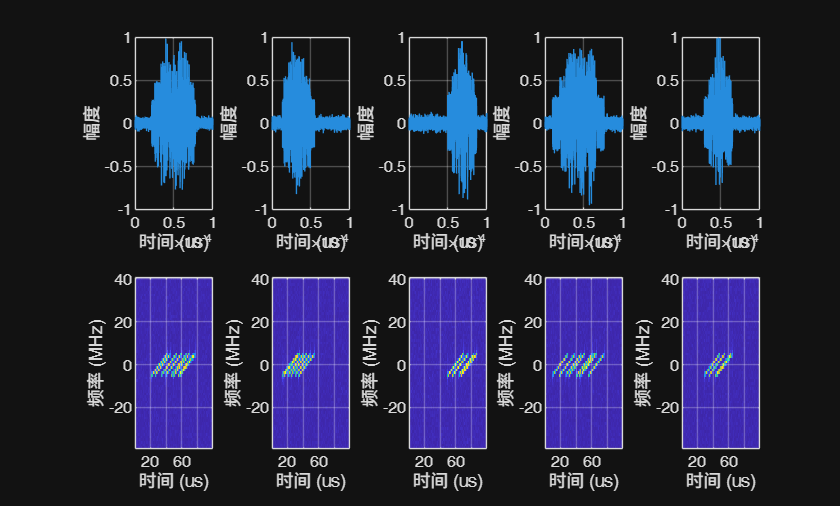

close all;
figure(1)
for i = 1:SAMPLE_NUM_S
    subplot(2,SAMPLE_NUM_S,i)
    t_axis = params.t_total;% 时间轴 us
    plot(t_axis, real(all_times(i,:)));
    xlabel('时间 (us)');
    ylabel('幅度');
    grid on;
    
    subplot(2,SAMPLE_NUM_S,SAMPLE_NUM_S+i)
    imagesc(T*1e6, F/1e6, abs(squeeze(all_stfts(i,:,:))) + eps);
    axis xy;
    xlabel('时间 (us)');
    ylabel('频率 (MHz)');
    grid on;

end